# Using SASA to approximate SC sigma

We compute the solvent-accessible surface area of a single DFAG side chain.

We set the Van der Waals radius for the computation to be 1/2 the LJ sigma of the beads, where BB beads have $$\sigma$ = 0.47$ = 0.47 nm, and SC beads have $$\sigma = 0.43$$ nm.

0.47/2

ans = 0.2350

0.43/2

ans = 0.2150

## DFAG SASA

Making the gratuitous assumption that the SASA corresponds to a spherical surface, we can compute the equivalent radius of that sphere:

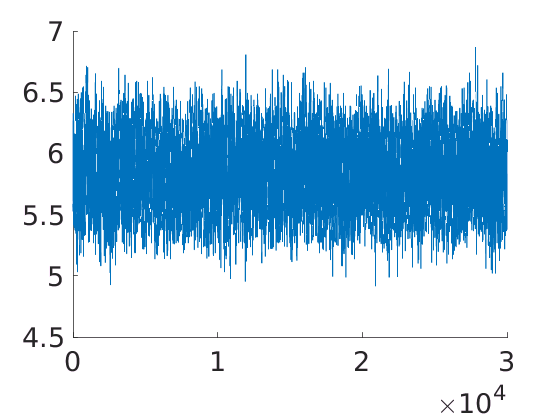

fname = '/home/rachael/coarsegraining/CG/DFAG/parameterization/BIbonded_eostre/340ns_params/dih_enf_full_tab/5_md';
f = [fname '/sasaSC1.xvg'];
figure()
hold on
set(gca,'fontsize',20)
sasaDFAG = importdata(f,' ',23);
plot(sasaDFAG.data(:,1),sasaDFAG.data(:,2))

sasaDFAG = sasaDFAG.data;

## Homodimer SASAs

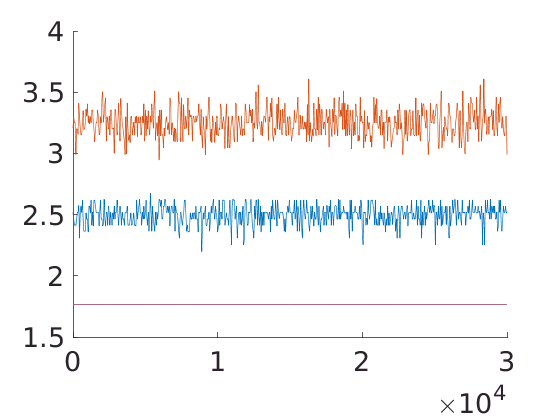

fnameD = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/homodimers/homoD/4_md/sasa';
fnameF = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/homodimers/homoF/4_md/sasa';
fnameA = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/homodimers/homoA/4_md/sasa';
fnameG = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/homodimers/homoG/4_md/sasa';
fD = [fnameD '/sasaSC1.xvg'];
fF = [fnameF '/sasaSC1.xvg'];
fA = [fnameA '/sasaSC1.xvg'];
fG = [fnameG '/sasaSC1.xvg'];
sasaD = importdata(fD,' ',23);
sasaF = importdata(fF,' ',23);
sasaA = importdata(fA,' ',23);
sasaG = importdata(fG,' ',23);
sasaD = sasaD.data;
sasaF = sasaF.data;
sasaA = sasaA.data;
sasaG = sasaG.data;
figure()
hold on
set(gca,'fontsize',20)
plot(sasaD(:,1),sasaD(:,2));
plot(sasaF(:,1),sasaF(:,2));
plot(sasaA(:,1),sasaA(:,2));
plot(sasaG(:,1),sasaG(:,2));

## Compute sigma from SASA

msasaDFAG = mean(sasaDFAG(:,2));
ssasaDFAG = std(sasaDFAG(:,2));
fprintf('SASA DFAG: %f +/- %f',msasaDFAG,ssasaDFAG);

SASA DFAG: 5.832893 +/- 0.230904

rsasaDFAG = sqrt(msasaDFAG/(4*pi));
srsasaDFAG = (ssasaDFAG/msasaDFAG)*rsasaDFAG; %percent error
fprintf('r of comparable sphere: %f +/- %f',rsasaDFAG,srsasaDFAG)

r of comparable sphere: 0.681298 +/- 0.026970

fprintf('sigma of comparable LJ sphere: %f +/- %f',2*rsasaDFAG,2*srsasaDFAG)

sigma of comparable LJ sphere: 1.362596 +/- 0.053940


msasaD = mean(sasaD(:,2));
ssasaD = std(sasaD(:,2));
rsasaD = sqrt(msasaD/(4*pi));
srsasaD = (ssasaD/msasaD)*rsasaD; %percent error
VsasaD = (4/3)*pi*rsasaD^3;
sVsasaD = (srsasaD/rsasaD)*VsasaD;

msasaF = mean(sasaF(:,2));
ssasaF = std(sasaF(:,2));
rsasaF = sqrt(msasaF/(4*pi));
srsasaF = (ssasaF/msasaF)*rsasaF; %percent error
VsasaF = (4/3)*pi*rsasaF^3;
sVsasaF = (srsasaF/rsasaF)*VsasaF;

msasaA = mean(sasaA(:,2));
ssasaA = std(sasaA(:,2));
rsasaA = sqrt(msasaA/(4*pi));
srsasaA = (ssasaA/msasaA)*rsasaA; %percent error
VsasaA = (4/3)*pi*rsasaA^3;
sVsasaA = (srsasaA/rsasaA)*VsasaA;

msasaG = mean(sasaG(:,2));
ssasaG = std(sasaG(:,2));
rsasaG = sqrt(msasaG/(4*pi));
srsasaG = (ssasaG/msasaG)*rsasaG; %percent error
VsasaG = (4/3)*pi*rsasaG^3;
sVsasaG = (srsasaG/rsasaG)*VsasaG;

VDFAG = VsasaD + VsasaF + VsasaA + VsasaG;
sVDFAG = sqrt(sVsasaD^2 + sVsasaF^2 + sVsasaA^2 + sVsasaG^2);

rVDFAG = (VDFAG*(3/(4*pi)))^(1/3);
srVDFAG = (sVDFAG/VDFAG)*rVDFAG;
fprintf('r of comparable volume: %f +/- %f',rVDFAG,srVDFAG)

r of comparable volume: 0.687903 +/- 0.011215

fprintf('sigma of comparable LJ sphere: %f +/- %f',2*rVDFAG,2*srVDFAG)

sigma of comparable LJ sphere: 1.375806 +/- 0.022430


VDAAA = VsasaD + 3*VsasaA;
rVDAAA = (VDAAA*(3/(4*pi)))^(1/3);
2*rVDAAA

ans = 1.2544


VDFFF = VsasaD + 3*VsasaF;
rVDFFF = (VDFFF*(3/(4*pi)))^(1/3);
2*rVDFFF

ans = 1.5693


VDAA = VsasaD + 2*VsasaA;
rVDAA = (VDAA*(3/(4*pi)))^(1/3);
2*rVDAA

ans = 1.1578


VD = VsasaD;
rVD = (VD*(3/(4*pi)))^(1/3);
2*rVD

ans = 0.8914

From this computation, the smallest sigma we are likely to reach is ~0.9, while the largest is ~1.6. If we want to test a little bit outside this range (especially since we may very well go to larger with some of the even bulkier side chains), 1.0, 1.5, 2.0 is a reasonable set of parameter values to test.